# **Redes Neuronais**

Trabalho prático CR - 2021/2022 (Alínea A)

clear all
close all
accuracyFinalTeste = 0;
accuracyFinalExemplos = 0;
nSim = 5;

for i=1 : nSim

### Topologia da rede neuronal

topologia = "Feedforward";
switch(topologia)
    case "Feedforward"
        net = feedforwardnet;
    case "Pattern"
        net = patternnet;
    case "Fitting"
        net = fitnet;
end

### Input da rede neuronal

folder = "imagens/start/*/*.png";
[input, tamanho] = process_images(folder);
target = gen_target(tamanho);

### Configurações da rede neuronal

% Função de Ativação
act_func = "hardlim";

% Função de Treino
trn_func = "trainlm";

% Função de Divisão
dvd_func = "dividerand";

% Épocas (iterações)
epochs = 1000;

net.layers{1}.transferFcn = act_func;
net.trainFcn = trn_func;
net.divideFcn = dvd_func;
net.trainParam.epochs = epochs;

### Treino da rede neuronal

[net, tr] = train(net, input, target);

### Simulação e desempenho da rede neuronal

Precisão total nos exemplos: 40.000


Precisao total nos testes: 0.000


Precisão total nos exemplos: 56.667


Precisao total nos testes: 40.000


Precisão total nos exemplos: 53.333


Precisao total nos testes: 20.000


Precisão total nos exemplos: 56.667


Precisao total nos testes: 0.000


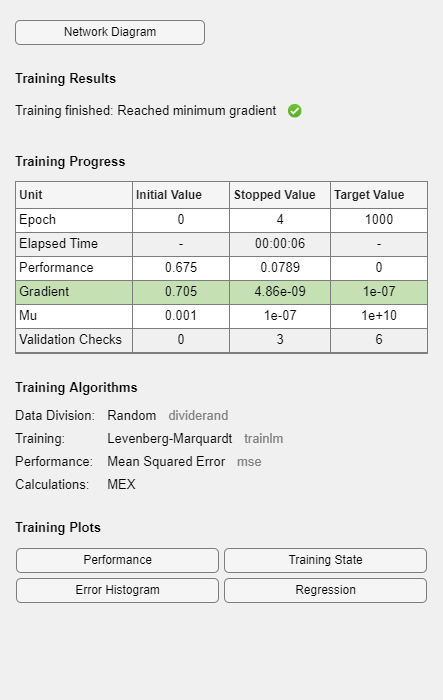

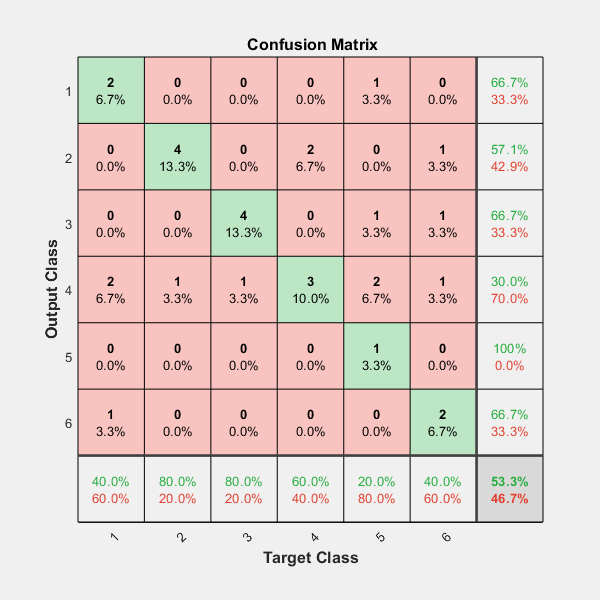

Precisão total nos exemplos: 53.333


Precisao total nos testes: 20.000


out = sim(net, input);
plotconfusion(target, out);
r=0;
for i=1:size(out,2)
  [a, b] = max(out(:,i));
  [c, d] = max(target(:,i));
  if b == d
      r = r+1;
  end
end
accuracy = r/size(out,2)*100;
fprintf('Precisão total nos exemplos: %.3f\n', accuracy)
accuracyFinalExemplos = accuracyFinalExemplos + accuracy;

TInput = input(:, tr.testInd);
TTargets = target(:, tr.testInd);
out = sim(net, TInput);
r = 0;
for i=1 : size(tr.testInd,2)
  [a, b] = max(out(:,i));
  [c, d] = max(TTargets(:,i));
  if b == d
      r = r+1;
  end
end
accuracy = r/size(tr.testInd,2)*100;
fprintf('Precisao total nos testes: %.3f\n', accuracy)
accuracyFinalTeste = accuracyFinalTeste + accuracy;
end

fprintf('\nMédia global final dos [Exemplos] depois de %i testes: %.3f\n', nSim, accuracyFinalExemplos/nSim);


Média global final dos [Exemplos] depois de 5 testes: 52.000


fprintf('Média global final dos [Testes] depois de %i testes: %.3f\n', nSim, accuracyFinalTeste/nSim);

Média global final dos [Testes] depois de 5 testes: 16.000
